clear; clc;

% Loading data
calib_rotate = load('calib1_rotate.mat');     % For magnetometer calibration
calib_straight = load('calib2_straight.mat'); % For IMU and ToF calibration

stationary_idx = calib_straight.out.GT_time.time <= 60;

% Task 1
task1_1 = load("task1_1.mat");
task1_2 = load("task1_2.mat");
task1_3 = load("task1_3.mat");
task1_4 = load("task1_4.mat");
task1_5 = load("task1_5.mat");
task1 = [task1_1, task1_2, task1_3, task1_4, task1_5];

% Task 2
task2_1 = load("task2_1.mat");
task2_2 = load("task2_2.mat");
task2_3 = load("task2_3.mat");
task2_4 = load("task2_4.mat");
task2_5 = load("task2_5.mat");
task2 = [task2_1, task2_2, task2_3, task2_4, task2_5];

    8.8078

Velocity X (X(3)): 0.084691
IMU Time: 0.0096154
    8.8080

Velocity X (X(3)): 0.16938
IMU Time: 0.019231
    8.8081

Velocity X (X(3)): 0.25408
IMU Time: 0.028846


Task 2_1 RMSE: 


Position RMSE: 6.3487 meters


Yaw RMSE: 75.3457 degrees


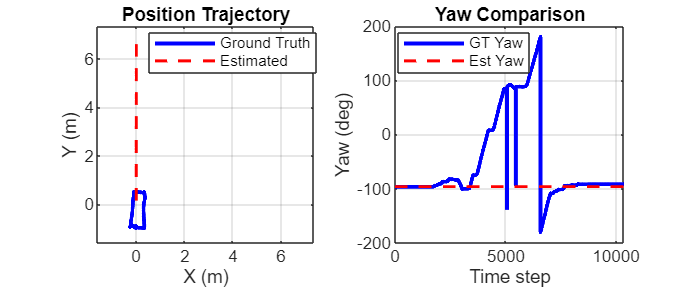

% 1. Calibrating sensors

% 2. Running EKF and storing RMSEs
task2_rmse = [0 0 0 0 0;
              0 0 0 0 0];
for i=1:1
    [X_Est, P_Est, GT] = myEKF(task2(i).out);

    disp("Task 2_" + num2str(i) + " RMSE: ");
    [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, task2(i).out.GT_rotation.signals.values);
    disp(['Position RMSE: ', num2str(pos_rmse), ' meters']);
    disp(['Yaw RMSE: ', num2str(rad2deg(yaw_rmse)), ' degrees']);

    task2_rmse(1, i) = pos_rmse;
    task2_rmse(2, i) = yaw_rmse;

    visualiseTrajectory(X_Est, GT, sprintf('task2_%d', i));
end


% 3. Comparing tajectories
% compareEKFTrajectory(X_Est, task2_1.out);

% Manual RMSE
% disp("Task 2 RMSE: ");
% [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, task2_1.out.GT_rotation.signals.values);
% disp(['Position RMSE: ', num2str(pos_rmse), ' meters']);
% disp(['Yaw RMSE: ', num2str(rad2deg(yaw_rmse)), ' degrees']);

function [X_Est, P_Est, GT] = myEKF(out)

    %% Extracting data %%
    % Loading calibration parameters
    persistent calib_params;
    if isempty(calib_params)
        if exist('calib_params.mat', 'file')
            calib_params = load('calib_params.mat');
        else
            error('Calibration file not found. Run calibrate_sensors.m first.');
        end
    end
    
    % Ground truth data
    GT_time = double(out.GT_time.time);
    GT_position = out.GT_position.signals.values;
    GT_rotation = out.GT_rotation.signals.values;
    for i=1:size(GT_rotation)
        if all(GT_rotation(i,:)==0)
            GT_rotation(i,:) = [1,0,0,0];
        end
    end

    % Sensor data
    accel_raw = out.Sensor_ACCEL.signals.values;
    accel_squeezed = squeeze(accel_raw);
    gyro_raw = out.Sensor_GYRO.signals.values;
    gyro_squeezed = squeeze(gyro_raw);
    mag_data = squeeze(out.Sensor_MAG.signals.values)';  % Magnetometer
    tof1_data = out.Sensor_ToF1.signals.values;          % ToF 1
    tof2_data = out.Sensor_ToF2.signals.values;          % ToF 2
    tof3_data = out.Sensor_ToF3.signals.values;          % ToF 3

    %% Initialisations %%
    eul_angles = quat2eul(GT_rotation(1,:), 'ZYX');
    X = [GT_position(1,1); 
         GT_position(1,2); 
         0;                
         0;
         eul_angles(1); 
         0];  % [X, Y, Vx, Vy, theta, omega]
    P = diag([0.01, 0.01, 0.1, 0.1, deg2rad(5), 0.1]);  % State Covariance Matrix
    Q = diag([0.2, 0.2, 0.2, 0.2, 0.05, 0.05]); % Process Noise Covariance Matrix

    %% Time & Index %%
    imu_dt = 1/104;  % IMU time (104 Hz)
    imu_idx = 1;
    imu_time = 0;

    mag_dt = 1/50;   % Magnetometer time (50 Hz)
    mag_idx = 1;
    mag_time = 0;

    tof_dt = 1/10;   % ToF time (10 Hz)
    tof_idx = 1;
    tof_time = 0;

    dt = 1/200;  % Ground truth time (200 Hz)

    n = length(GT_time);
    num_mag_samples = size(mag_data,1);
    num_tof_samples = size(tof1_data,1);

    % Initialising output variables
    X_Est = zeros(n, 6);
    P_Est = zeros(6, 6, n);
    GT = zeros(n, 3);

    %% Main EKF Loop %%
    for i=1:n

        %% PART 1: Prediction Step %%
        % The prediction step is based on the IMU (both gyroscope and accelerometer)

        current_time = GT_time(i);
        
        while imu_idx <= size(accel_squeezed, 1)

            if imu_time > current_time
                break;
            end
    
            % Get calibrated IMU measurements
            a_body = (accel_squeezed(:, imu_idx)' - calib_params.accel_bias(1:2)');
            gyro_z = deg2rad(gyro_squeezed(3, imu_idx)) - calib_params.gyro_bias(3);  % Extract z-axis gyro value
            
            % Transform acceleration to world frame
            R = [cos(X(5)) -sin(X(5)); 
                 sin(X(5))  cos(X(5))];
            a_world = R * a_body;
            disp(a_world(1));
            
            % State prediction: Position + Velocity
            X(1) = X(1) + X(3)*imu_dt + 0.5*a_world(1)*imu_dt^2;
            X(2) = X(2) + X(4)*imu_dt + 0.5*a_world(2)*imu_dt^2;
            X(3) = X(3) + a_world(1)*imu_dt;
            X(4) = X(4) + a_world(2)*imu_dt;
            X(5) = X(5) + gyro_z*imu_dt;  % Update yaw with gyro_z
            X(6) = X(6) + gyro_z*imu_dt;  % Update angular velocity (if required)
        
            disp(['Velocity X (X(3)): ', num2str(X(3))]);
        
            % Jacobian F (for 6-state vector)
            F = [1 0 imu_dt 0 0 0;
                 0 1 0      imu_dt 0 0;
                 0 0 1      0     0 0;
                 0 0 0      1     0 0;
                 0 0 0      0     1 imu_dt;
                 0 0 0      0     0 1];
        
            % Predicting Covariance
            P = F * P * F' + Q;
        
            % Updating IMU time and index
            imu_idx = imu_idx + 1;
            imu_time = imu_time + imu_dt;
            disp(['IMU Time: ', num2str(imu_time)]);
            current_time = GT_time(i) + imu_time;
        
        end

        %% PART 2: Update Step %%
        % Magnetometer update
        if (mag_idx <= num_mag_samples) && (mag_time <= current_time)
            mag_raw = mag_data(mag_idx,:)';
            mag_calib = calib_params.A_mag * (mag_raw - calib_params.b_mag');
            if norm(mag_calib) > 0.61762  % Threshold for valid measurement
                z_mag = atan2(mag_calib(2), mag_calib(1));
                if abs(wrapToPi(z_mag - X(5))) < 1.4201  % Yaw threshold for correction
                    [X, P] = ekf_update(X, P, [0 0 0 0 1 0], z_mag, 0.016755);
                end
            end
            mag_idx = mag_idx + 1;
            mag_time = mag_time + mag_dt;
        end

        % ToF Updates
        arena_size = 2.4; % meters
        if (tof_idx <= num_tof_samples) && (tof_time <= current_time)
            if tof1_data(tof_idx,4) == 0 % Forward-facing ToF
                expected_dist = (arena_size/2) - X(2);
                z_tof1 = tof1_data(tof_idx,1) - calib_params.tof_bias(1);
                [X, P] = ekf_update(X, P, [0 1 0 0 0 0], z_tof1 - expected_dist, 0.01);
            end
            
            if tof2_data(tof_idx,4) == 0 % Left-facing ToF
                expected_dist = (arena_size/2) + X(1);
                z_tof2 = tof2_data(tof_idx,1) - calib_params.tof_bias(2);
                [X, P] = ekf_update(X, P, [1 0 0 0 0 0], z_tof2 - expected_dist, 0.01);
            end
            
            if tof3_data(tof_idx,4) == 0 % Right-facing ToF
                expected_dist = (arena_size/2) - X(1);
                z_tof3 = tof3_data(tof_idx,1) - calib_params.tof_bias(3);
                [X, P] = ekf_update(X, P, [1 0 0 0 0 0], z_tof3 - expected_dist, 0.01);
            end
        
            tof_idx = tof_idx + 1;
            tof_time = tof_time + tof_dt;
        end

        % Making sure yaw is in range
        X(5) = wrapToPi(X(5));

        % Storing output
        X_Est(i,:) = X';
        P_Est(:,:,i) = P;
        
        % Ground truth data
        current_eul = quat2eul(GT_rotation(i,:), 'ZYX');
        GT(i,:) = [GT_position(i,1), GT_position(i,2), current_eul(1)];
    end
end

% Helper function to perform the EKF update
function [X_updated, P_updated] = ekf_update(X, P, H, z, R)
    K = P * H' / (H * P * H' + R);
    X_updated = X + K * (z - H * X);
    P_updated = (eye(6) - K * H) * P * (eye(6) - K * H)' + K * R * K';
end

% RMSE Calculation
function [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, GT_rotation)
    % Ensure inputs are column vectors
    GT_x = GT(:,1);
    GT_y = GT(:,2);
    GT_yaw = GT(:,3);
    
    % Calculate position RMSE (X and Y combined)
    pos_error = sqrt((X_Est(:,1) - GT_x).^2 + (X_Est(:,2) - GT_y).^2);
    pos_rmse = sqrt(mean(pos_error.^2));
    
    % Calculate yaw RMSE
    est_yaw = X_Est(:,5);
    
    % Ensure both yaw vectors are same length
    min_len = min(length(est_yaw), length(GT_yaw));
    est_yaw = est_yaw(1:min_len);
    GT_yaw = GT_yaw(1:min_len);
    
    % Wrap angles to [-pi, pi] for proper difference calculation
    yaw_diff = wrapToPi(est_yaw - GT_yaw);
    
    yaw_rmse = sqrt(mean(yaw_diff.^2));
end

function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end

function visualiseTrajectory(X_Est, GT, dataset_name)
    figure('Name', ['Trajectory: ', dataset_name], 'Position', [100 100 1200 500]);
    
    % Position Plot
    subplot(1,2,1);
    plot(GT(:,1), GT(:,2), 'b-', 'LineWidth', 2, 'DisplayName', 'Ground Truth');
    hold on;
    plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Estimated');
    axis equal;
    
    % Set dynamic axis limits based on the data range
    min_x = min(min(GT(:,1)), min(X_Est(:,1)));
    max_x = max(max(GT(:,1)), max(X_Est(:,1)));
    min_y = min(min(GT(:,2)), min(X_Est(:,2)));
    max_y = max(max(GT(:,2)), max(X_Est(:,2)));
    
    % Add some padding around the axis limits to prevent data points from touching the edges
    padding = 1 * (max_x - min_x);
    
    xlim([min_y - padding, max_y + padding]);
    ylim([min_y - padding, max_y + padding]);
    
    xlabel('X (m)'); ylabel('Y (m)');
    title('Position Trajectory');
    legend('Location', 'best');
    grid on;
    
    % Yaw Plot
    subplot(1,2,2);
    t = 1:length(GT(:,3));
    plot(t, rad2deg(GT(:,3)), 'b-', 'LineWidth', 2, 'DisplayName', 'GT Yaw');
    hold on;
    plot(t, rad2deg(X_Est(:,5)), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Est Yaw');
    xlabel('Time step'); ylabel('Yaw (deg)');
    title('Yaw Comparison');
    legend('Location', 'best');
    grid on;
    
    % Save figure
    saveas(gcf, ['trajectory_', dataset_name, '.png']);
end

